% avoid obstacles  using SAC  for Mobile robot
% map created
load simpleMap.mat
load complexMap.mat
% load map6.mat
map1= 1;
if map1==1
    mapMatrix=simpleMap
else
    mapMatrix=complexMap
end

mapMatrix = 26×27 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

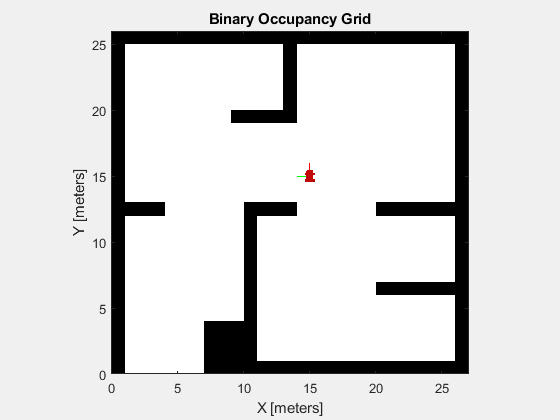

% mapMatrix = simpleMap
%load exampleHelperOfficeAreaMap office_area_map
% map = mapMaze(30,2,'MapSize',[30 30],'MapResolution',3);
% map1 = binaryOccupancyMap(map,1);
% mapnumber= rand;
mapScale = 1;
% range sensor 
% scanAngles = [-3*pi/8 : pi/8 :3*pi/8];
scanAngles = [0 : 2*pi/179 :2*pi];
maxRange = 4;
lidarNoiseVariance = 0.1^2;
lidarNoiseSeeds = randi(intmax,size(scanAngles));

% robot parameter0
% Max speed parameters
maxLinSpeed = 1.0; %0.3
maxAngSpeed = 1.0; %0.3
device = 'cpu';
% Initial pose of the robot
initX = 15;  %18
initY = 15;
initTheta = pi/2;

% Goal pose of the robot
goalX = 5; %5
goalY = 5; %5
goalTheta = -pi/2;

% minimum distance before angle correction (final Approach)
min_angle_dis=1;

%is done condition
minimum_lidar_to_wall=0.25;
%reach goal condition
goal_X_max_tolarance = goalX +0.01;
goal_X_min_tolarance = goalX -0.01;
goal_Y_max_tolarance = goalY +0.01;
goal_Y_min_tolarance = goalY -0.01;

goalTheta_max_tolarance = goalTheta +0.874; %5 degree
goalTheta_min_tolarance = goalTheta -0.874;

maximum_x_y=1000;

%SAC observation parameter additional observation other than lidar scan
additional_observation=10;

fig = figure("Name","Map");
set(fig, "Visible", "on");
ax = axes(fig);

show(binaryOccupancyMap(mapMatrix),"Parent",ax);
hold on
plotTransforms([initX, initY, 0], eul2quat([initTheta, 0, 0]), "MeshFilePath","groundvehicle.stl", "View", "2D");
light;
hold off


% environment interface
mdl = "AvoidObstaclesMobileRobot";
Tfinal = 30;
sampleTime = 0.1;

agentBlk = mdl + "/Agent";
open_system(mdl)
open_system(mdl + "/Environment")

% define observation parameters
observationwithposeerror=numel(scanAngles)+additional_observation;
obsInfo = rlNumericSpec([observationwithposeerror 1],...
    "LowerLimit",ones(observationwithposeerror,1)*-maximum_x_y,...
    "UpperLimit",ones(observationwithposeerror,1)*maximum_x_y);

%obsInfo = rlNumericSpec([observationwithposeerror 1],...
 %   "LowerLimit",zeros(observationwithposeerror,1),...
 %   "UpperLimit",ones(observationwithposeerror,1)*maxRange);
numObservations = obsInfo.Dimension(1);
% define action parameters
numActions = 2;
actInfo = rlNumericSpec([numActions 1],...
    "LowerLimit",-1,...
    "UpperLimit",1);
% build environment interface
env = rlSimulinkEnv(mdl,agentBlk,obsInfo,actInfo);
env.ResetFcn = @(in)RLAvoidObstaclesResetFcn(in,scanAngles,maxRange,simpleMap)

env = <a href=""matlab: help rl.env.SimulinkEnvWithAgent"">SimulinkEnvWithAgent</a> with properties:

           Model : AvoidObstaclesMobileRobot
      AgentBlock : AvoidObstaclesMobileRobot/Agent
        ResetFcn : @(in)RLAvoidObstaclesResetFcn(in,scanAngles,maxRange,simpleMap)
  UseFastRestart : on


env.UseFastRestart = "off"

env = <a href=""matlab: help rl.env.SimulinkEnvWithAgent"">SimulinkEnvWithAgent</a> with properties:

           Model : AvoidObstaclesMobileRobot
      AgentBlock : AvoidObstaclesMobileRobot/Agent
        ResetFcn : @(in)RLAvoidObstaclesResetFcn(in,scanAngles,maxRange,simpleMap)
  UseFastRestart : off



% % SAC agent 
statePath1 = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(400,'Name','CriticStateFC1')
    reluLayer('Name','CriticStateRelu1')
    fullyConnectedLayer(300,'Name','CriticStateFC2')
    ];
actionPath1 = [
    featureInputLayer(numActions,'Normalization','none','Name','action')
    fullyConnectedLayer(300,'Name','CriticActionFC1')
    ];
commonPath1 = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(1,'Name','CriticOutput')
    ];

criticNet = layerGraph(statePath1);
criticNet = addLayers(criticNet,actionPath1);
criticNet = addLayers(criticNet,commonPath1);
criticNet = connectLayers(criticNet,'CriticStateFC2','add/in1');
criticNet = connectLayers(criticNet,'CriticActionFC1','add/in2');

% create  critic using rlRepresentation
%criticOpts = rlRepresentationOptions("LearnRate",1e-3,"L2RegularizationFactor",1e-4,"GradientThreshold",1);
%critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,"Observation",{'State'},"Action",{'Action'},criticOpts);
criticOptions = rlRepresentationOptions('Optimizer','adam','LearnRate',1e-3,... 
                                        'GradientThreshold',1,'L2RegularizationFactor',2e-4);
critic1 = rlQValueRepresentation(criticNet,obsInfo,actInfo,...
    'Observation',{'observation'},'Action',{'action'},criticOptions);
critic2 = rlQValueRepresentation(criticNet,obsInfo,actInfo,...
    'Observation',{'observation'},'Action',{'action'},criticOptions);
% create actor
% network(https://uk.mathworks.com/help/reinforcement-learning/ref/rlsacagent.html)
statePath = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(400, 'Name','commonFC1')
    reluLayer('Name','CommonRelu')];
meanPath = [
    fullyConnectedLayer(300,'Name','MeanFC1')
    reluLayer('Name','MeanRelu')
    fullyConnectedLayer(numActions,'Name','Mean')
    ];
stdPath = [
    fullyConnectedLayer(300,'Name','StdFC1')
    reluLayer('Name','StdRelu')
    fullyConnectedLayer(numActions,'Name','StdFC2')
    softplusLayer('Name','StandardDeviation')];

concatPath = concatenationLayer(1,2,'Name','GaussianParameters');

actorNetwork = layerGraph(statePath);
actorNetwork = addLayers(actorNetwork,meanPath);
actorNetwork = addLayers(actorNetwork,stdPath);
actorNetwork = addLayers(actorNetwork,concatPath);
actorNetwork = connectLayers(actorNetwork,'CommonRelu','MeanFC1/in');
actorNetwork = connectLayers(actorNetwork,'CommonRelu','StdFC1/in');
actorNetwork = connectLayers(actorNetwork,'Mean','GaussianParameters/in1');
actorNetwork = connectLayers(actorNetwork,'StandardDeviation','GaussianParameters/in2');
% create Stochastic actor representation
actorOptions = rlRepresentationOptions('Optimizer','adam','LearnRate',1e-3,...
                                       'GradientThreshold',1,'L2RegularizationFactor',1e-5);

actor = rlStochasticActorRepresentation(actorNetwork,obsInfo,actInfo,actorOptions,...
    'Observation',{'observation'});
%actorOptions = rlRepresentationOptions("Optimizer","adam", LearnRate",1e-4,"L2RegularizationFactor",1e-4,"GradientThreshold",1);
%actor = rlDeterministicActorRepresentation(actorNetwork,obsInfo,actInfo,"Observation",{'State'},"Action",{'Action'},actorOptions);
%actor = rlStochasticActorRepresentation(actorNetwork,obsInfo,actInfo,"Observation",{'State'},"Action",{'Action'}, actorOptions);
%actor = rlStochasticActorRepresentation(actorNetwork, obsInfo,actInfo, "Observation",{'state'},actorOptions);
% create SAC agent
SampleTime = 0.1

SampleTime = 0.1000

agentOptions = rlSACAgentOptions;
agentOptions.SampleTime = SampleTime;
agentOptions.DiscountFactor = 0.99;
agentOptions.TargetSmoothFactor = 1e-3;
agentOptions.ExperienceBufferLength = 1e5;
agentOptions.MiniBatchSize = 32;
agentOptions.SaveExperienceBufferWithAgent =true;
agentOptions.ResetExperienceBufferBeforeTraining = true;
%agentOpts.NoiseOptions.Variance = 0.1;
%agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;
%% Create SAC agent using actor, critics, and options
agentOptions

agentOptions =   rlSACAgentOptions with properties:

                   EntropyWeightOptions: [1×1 rl.option.EntropyWeightOptions]
                  PolicyUpdateFrequency: 1
                  CriticUpdateFrequency: 1
                      NumWarmStartSteps: 64
              NumGradientStepsPerUpdate: 1
           UseDeterministicExploitation: 0
                     TargetSmoothFactor: 1.0000e-03
                  TargetUpdateFrequency: 1
    ResetExperienceBufferBeforeTraining: 1
          SaveExperienceBufferWithAgent: 1
                         SequenceLength: 1
                          MiniBatchSize: 32
                    NumStepsToLookAhead: 1
                 ExperienceBufferLength: 100000
                             SampleTime: 0.1000
                         DiscountFactor: 0.9900

obstacleAvoidanceAgent = rlSACAgent(actor,[critic1 critic2],agentOptions);
open_system(mdl + "/Agent")

% train agent
maxEpisodes = 1000;
maxSteps = ceil(Tfinal/sampleTime);
trainOpts = rlTrainingOptions(...
    "MaxEpisodes",maxEpisodes, ...
    "MaxStepsPerEpisode",maxSteps, ...
    "ScoreAveragingWindowLength",50, ...
    "StopTrainingCriteria","AverageReward", ...
    "StopTrainingValue",20000, ...
    "Verbose", true, ...
    "Plots","training-progress");
trainOpts.SaveAgentCriteria = "EpisodeReward";
trainOpts.SaveAgentValue = 10000;

% plot(env)
% trainOpts.UseParallel = true;
% trainOpts.ParallelizationOptions.Mode = "async";
% trainOpts.ParallelizationOptions.DataToSendFromWorkers = "experiences";
% trainOpts.ParallelizationOptions.StepsUntilDataIsSent = -1;
%trainOpts

% doTraining
doTraining = false; % Toggle this to true for training. 

if doTraining
    % Load the agent from the previous session
   load ('sim_3300.mat', 'obstacleAvoidanceAgent')
 %    load ('Agent500.mat', 'saved_agent')
%     obstacleAvoidanceAgent = saved_agent;
    % Train the agent.
    trainingStats = train(obstacleAvoidanceAgent,env,trainOpts);
    save ('sim_3800.mat','obstacleAvoidanceAgent');
    %save(trainOpts.SaveAgentDirectory + "/sim_200.mat",'obstacleAvoidanceAgent')
else
    % Load pretrained agent for the example.
    %load AvoidObstaclesAgent obstacleAvoidanceAgent    %load netavoid_f.mat obstacleAvoidanceAgent   
    load sim_3300.mat obstacleAvoidanceAgent 
    %load Agent500.mat saved_agent 
end

Error using load
'sim_3300.mat' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\ubai\Documents\MATLAB\RL\SAC_MR
    C:\Users\ubai\Documents\MATLAB\RL\SAC_MR\savedAgents

Change the MATLAB current folder or add its folder to the MATLAB path.


rng(0);
%simulate 
out = sim("AvoidObstaclesMobileRobot.slx");
%visualization
for i = 1:10:size(out.range, 3)
    u = out.pose(i, :);
    r = out.range(:, :, i);
    AvoidObstaclesPosePlot(u, mapMatrix, mapScale, r, scanAngles, ax);
end












